# Hypothesis testing

clc;
close all;
clear variables;

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

## Parameters

% ma = [3; -4]; 
% mb = [10; -4];

ma = [3; -4]; 
mb = [6; -4];

% sigma_a = [1.7; 3];
% sigma_b = [3; 1.4];

sigma_a = [4; 3];
sigma_b = [3; 1.4];

rho_a = 0.6;
rho_b = 0.7;

num_a = 5000;
sum_b = 5000;

## Samples

A = Samples(ma, sigma_a, rho_a,  num_a);
B = Samples(mb, sigma_b, rho_b, sum_b);

### Plotting


figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples with constant pdf countours');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

syms x_1 x_2 real
X = [x_1; x_2];

line_width = 3;


$$f(X) = const$$


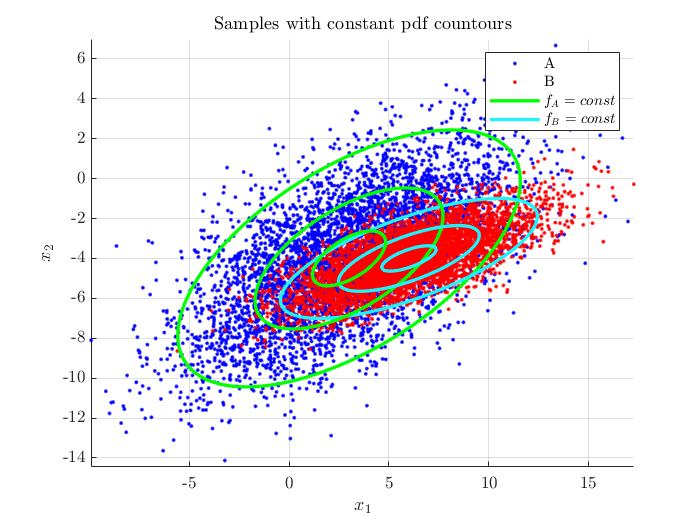

for const_pdf_val = [0.1 0.5 0.9]
    fimplicit(exp(-0.5 * (X - A.M)' * A.cov_mat ^ (-1) * (X - A.M)) == const_pdf_val, 'Color', '#00ff00', 'LineWidth', 2)
    fimplicit(exp(-0.5 * (X - B.M)' * B.cov_mat ^ (-1) * (X - B.M)) == const_pdf_val, 'Color', '#1AF4FF', 'LineWidth', 2)
end
labels{end+1} = '$f_A = const$';
labels{end+1} = '$f_B = const$';
leg = legend(labels);
set(leg,'Interpreter','latex');

figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title("Samples and the discrimination line - Bayes' test");
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

## Bayes' test of least error


$$h(X) = -ln\left(\frac{f_1}{f_2}\right) = ln\left(\frac{P_1}{P_2}\right)$$


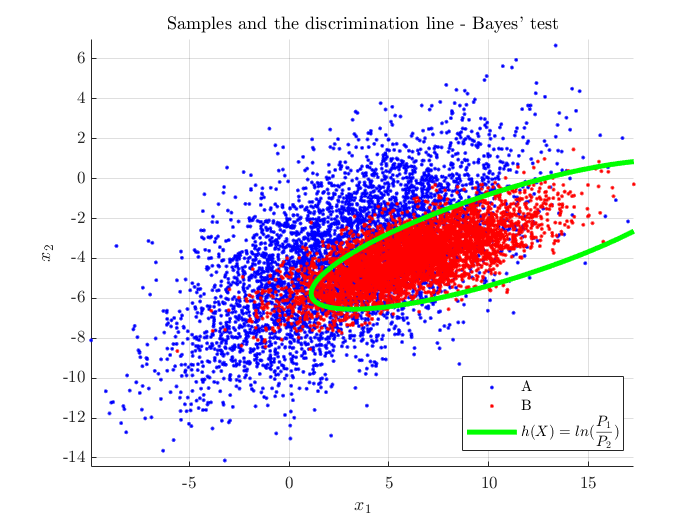

P = [A.num / (A.num + B.num); B.num / (A.num + B.num)];

threshold = log(P(1) / P(2));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_1}{P_2})$';

leg = legend(labels, "Location","best");
set(leg,'Interpreter','latex');

### Error estimation

#### Histogram

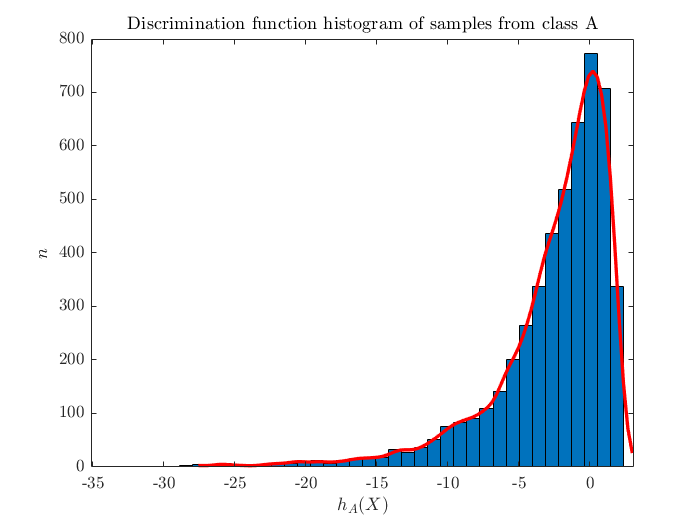

h_a = A.discrimination_function(B, 1);
n_bins = 40;
distribution_name = 'kernel';


figure();
histfit(h_a, n_bins, distribution_name);

title('Discrimination function histogram of samples from class A', "Interpreter","latex")
xlabel('$h_A(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

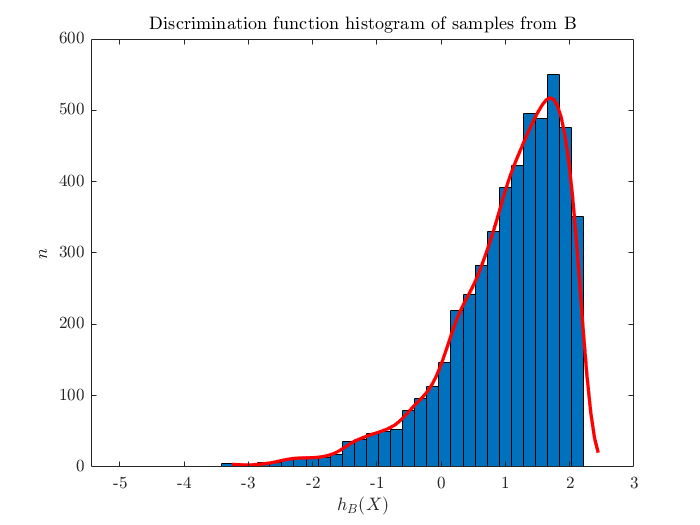

h_b = B.discrimination_function(A, 2);

figure();
histfit(h_b, n_bins, distribution_name);
title('Discrimination function histogram of samples from B', "Interpreter","latex")
xlabel('$h_B(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

#### PDF approximation

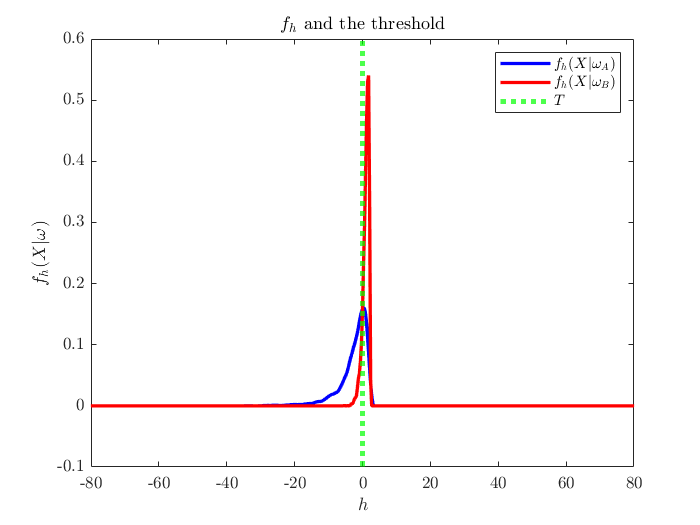

x_a = (-110:0.001:110)';
[y_a, fitobject_a] = approximate_pdf(h_a, x_a);

x_b = x_a;
[y_b, fitobject_b] = approximate_pdf(h_b, x_b);

figure();
plot(fitobject_a, 'b');
hold on;
plot(fitobject_b, 'r');

xline(threshold, 'g:', 'LineWidth', 3)
set(findall(gca, 'Type', 'Line'),'LineWidth', 2);

legend('$f_h(X|\omega_A)$', '$f_h(X|\omega_B)$', '$T$', "Interpreter","latex")
xlim([-80, 80])
title("$f_h$ and the threshold", "Interpreter","latex")
xlabel("$h$", "Interpreter","latex")
ylabel("$f_h(X|\omega)$", "Interpreter","latex")

#### Error estimates

% TODO da li sam ovde nesto omasio, mozda sam zamenio 1 i 2?
h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
h_eps_2 = integrate(fitobject_b, threshold, min(x_b));

freqentist_eps_1 = length(h_a(h_a > threshold)) / length(h_a);
freqentist_eps_2 = length(h_b(h_b < threshold)) / length(h_b);
error_approx_table = table(h_eps_1, h_eps_2, freqentist_eps_1, freqentist_eps_2)

error_approx_table = 1×4 table
    h_eps_1    h_eps_2    freqentist_eps_1    freqentist_eps_2
    _______    _______    ________________    ________________

    0.30119    0.12925         0.3016              0.1262     


total_error_h = h_eps_1 * P(1) + h_eps_2 * P(2);
total_error_freq = freqentist_eps_1 * P(1) + freqentist_eps_2 * P(2);
total_error_table = table(total_error_h, total_error_freq)

total_error_table = 1×2 table
    total_error_h    total_error_freq
    _____________    ________________

       0.21522            0.2139     


## Min-max test


P1_range = 0.0:0.01:1;
risk = zeros(length(P1_range), 1);

for i = 1:length(P1_range)
    P2 = 1 - P1_range(i);
    threshold = log(P1_range(i) / P2);
    
    h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
    h_eps_2 = integrate(fitobject_b, threshold, min(x_b));
    
    risk(i) = P1_range(i) * h_eps_1 + P2 * h_eps_2;
    
end

### Optimal risk

figure();
hold on;

plot(P1_range, risk);

[max_risk, argmax] = max(risk);
P1_max_risk = P1_range(argmax)

P1_max_risk = 0.6200

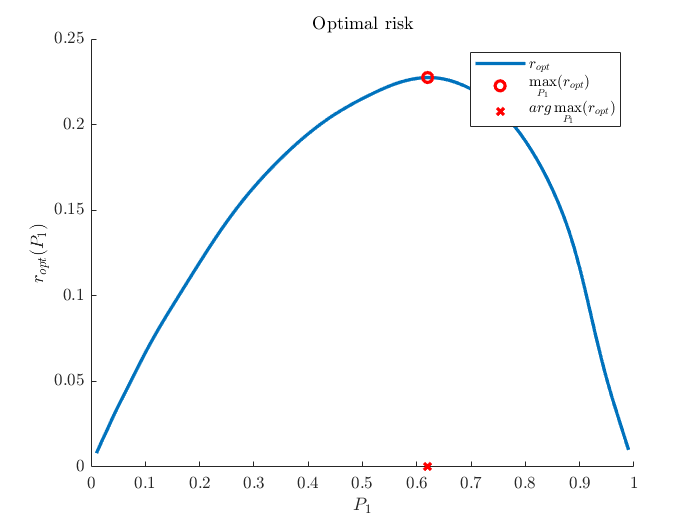

plot(P1_max_risk, max_risk, 'ro')
plot(P1_max_risk, 0, 'rx')

set(findall(gca, 'Type', 'Line'),'LineWidth', 2);

legend("$r_{opt}$", "$\max\limits_{P_1}(r_{opt})$", "$ arg\max \limits_{P_1}(r_{opt})$")
title("Optimal risk")
xlabel("$P_1$")
ylabel("$r_{opt} (P_1)$")

### Min-max test classifier

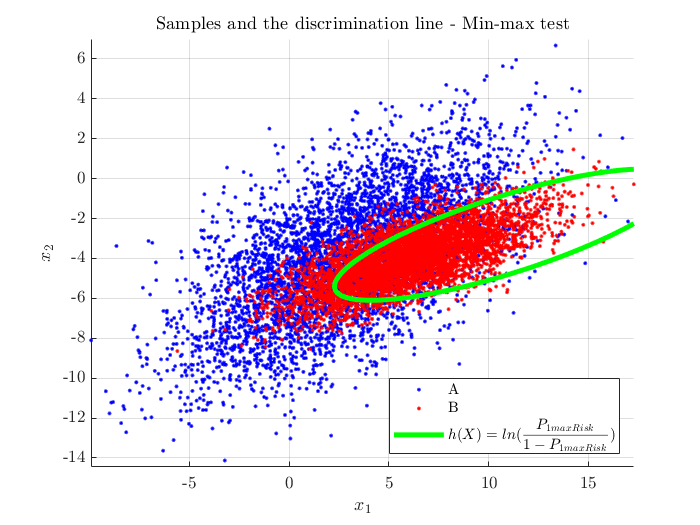

figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples and the discrimination line - Min-max test');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

threshold = log(P1_max_risk / (1 - P1_max_risk));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_{1 maxRisk}}{1 - P_{1 maxRisk}})$';

leg = legend(labels, "Location","southeast");

### Error estimates

% TODO da li sam ovde nesto omasio, mozda sam zamenio 1 i 2?
h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
h_eps_2 = integrate(fitobject_b, threshold, min(x_b));

freqentist_eps_1 = length(h_a(h_a > threshold)) / length(h_a);
freqentist_eps_2 = length(h_b(h_b < threshold)) / length(h_b);
error_approx_table = table(h_eps_1, h_eps_2, freqentist_eps_1, freqentist_eps_2)

error_approx_table = 1×4 table
    h_eps_1    h_eps_2    freqentist_eps_1    freqentist_eps_2
    _______    _______    ________________    ________________

    0.22281    0.23516         0.2194              0.2326     


total_error_h = h_eps_1 * P(1) + h_eps_2 * P(2);
total_error_freq = freqentist_eps_1 * P(1) + freqentist_eps_2 * P(2);
total_error_table = table(total_error_h, total_error_freq)

total_error_table = 1×2 table
    total_error_h    total_error_freq
    _____________    ________________

       0.22899            0.226      


### Comparison

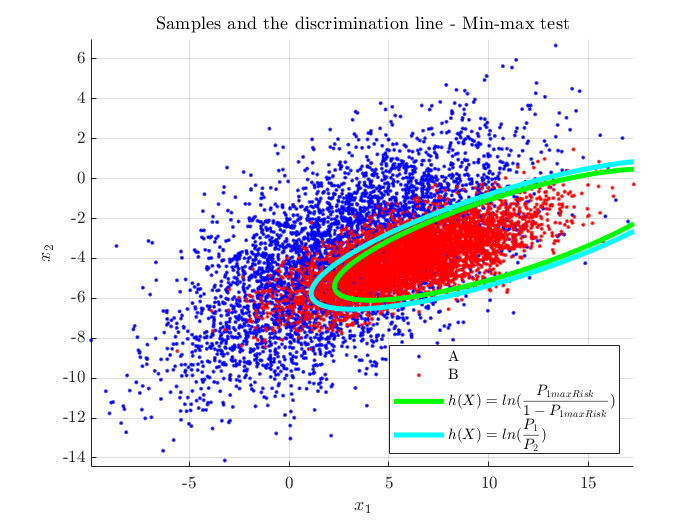

figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples and the discrimination line - Min-max test');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

threshold = log(P1_max_risk / (1 - P1_max_risk));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));

fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_{1 maxRisk}}{1 - P_{1 maxRisk}})$';

fimplicit(h == log(P(1) / P(2)), 'Color', 'c', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_1}{P_2})$';

leg = legend(labels, "Location","southeast");

% TODO mozda novi uzorci sa drugim P1 P2 pa kao da se vidi da je isti rizik

## Wald's sequential hypothesis test

sm = 0;
m = 0;

m_array = [m];
sm_array = [sm];

eps_1 = 1e-7;
eps_2 = 2e-4;

limit_a = -log((1 - eps_1) / eps_2)

limit_a = -8.5172

limit_b = -log(eps_1 / (1 - eps_2))

limit_b = 16.1179

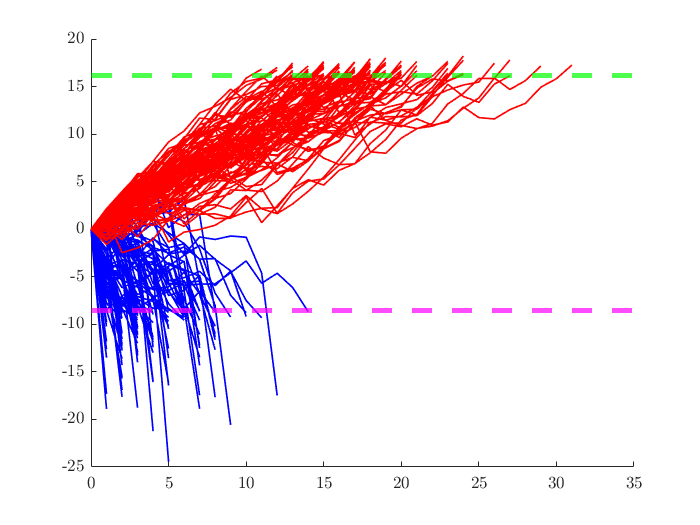

figure();
hold on;

N = 100;

mean_m_a_array = zeros(N, 1);
mean_m_b_array = zeros(N, 1);

for i = 1:N
    while true
        m = m + 1;
        m_array(end+1) = m;
    
        sample = Samples(ma, sigma_a, rho_a,  1);
        
        sm = sm + sample.discrimination_function(B, 1);
        sm_array(end+1) = sm;
        if (sm < limit_a)
            break;
        end
    end
    
    mean_m_a_array(i) = m;
    
    plot(m_array, sm_array, 'b')  
    
    sm = 0;
    m = 0;
    
    m_array = [m];
    sm_array = [sm];
end
    
for i = 1:N
    while true
        m = m + 1;
        m_array(end+1) = m;
    
        sample = Samples(mb, sigma_b, rho_b,  1);
        
        sm = sm + sample.discrimination_function(A, 2);
        sm_array(end+1) = sm;
        if (sm > limit_b)
            break;
        end
    end
    
    mean_m_b_array(i) = m;
    plot(m_array, sm_array, 'r')  
    
    sm = 0;
    m = 0;
    
    m_array = [m];
    sm_array = [sm];
end

yline(limit_a, 'm--', "LineWidth", 3)
yline(limit_b, 'g--', "LineWidth", 3)
set(findall(gca, 'Type', 'Line'),'LineWidth', 1);

mean(mean_m_a_array)

ans = 4.5500

mean(mean_m_b_array)

ans = 17.9500